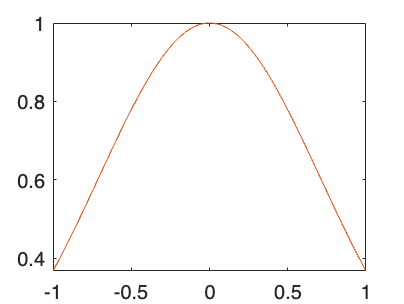

%Exercise 3
clear
% Problem 1
x = -1:0.01:1;

% Polynomial of degree = 10
% For evenly spacing at -1 and 1
% and chebyysev interpolation
x10 = linspace(-1,1,11);
y10 = exp(-x10.^2);
c10 = newtdd(x10, y10, 11);
yrange10 = nest(10, c10, x, x10);
yche10 = exp_chev(11);

% Polynomial of degree = 20
% For evenly spacing at -1 and 1
% and chebyysev interpolation
x20 = linspace(-1,1,21);
y20 = exp(-x20.^2);
c20 = newtdd(x20, y20, 21);
yrange20 = nest(20, c20, x, x20);
yche20 = exp_chev(21);

% Ploting degree of 10
% For evenly spacing at -1 and 1
% and chebyysev interpolation
plot(x,yrange10);
hold on
plot(x, yche10)
hold off

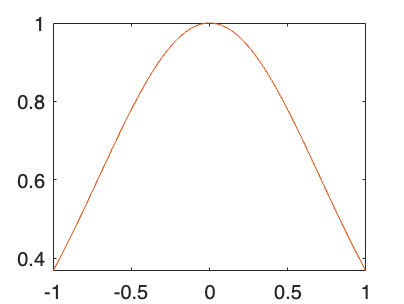


% Ploting degree of 20 
% For evenly spacing at -1 and 1
% and chebyysev interpolation
plot(x,yrange20);
hold on
plot(x, yche20)
hold off

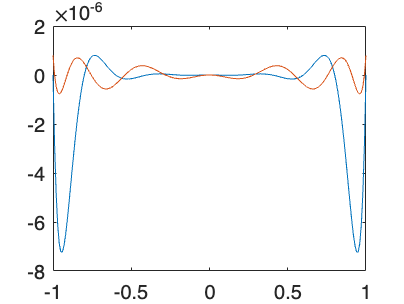


% Plot the error of degree = 10
% For evenly spacing at -1 and 1
% and chebyysev interpolation
plot(x, exp(-x.^2) - yrange10); % blue
hold on
plot(x, exp(-x.^2) - yche10); % orange
hold off

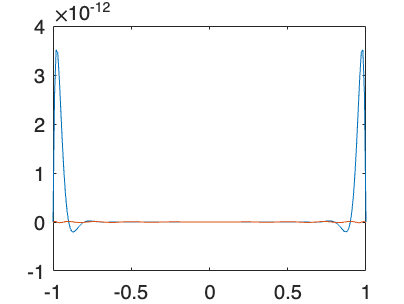


% Plot the error of degree = 20
% For evenly spacing at -1 and 1
% and chebyysev interpolation
plot(x, exp(-x.^2) - yrange20); % blue
hold on
plot(x, exp(-x.^2) - yche20); % orange
hold off


% From the plots, Runge phenomenon is not observed in the polynomial charts
% However the Runge phenomenon is observe in the error charts
% So, error is still have extreme variation near the end points

% Problem 2
clear
%a
syms x
s0a(x) = x^3 + x - 1; % [0,1]
s1a(x) = -(x-1)^3 + 3*(x-1)^2 + 3*(x-1) + 1; % [1,2]
% property 1
s0a(1) == s1a(1)

$$ans = 1=1$$

% property 2
s0a_1 = diff(s0a);
s1a_1 = diff(s1a);
s0a_1(1) == s1a_1(1) % false

$$ans = 4=3$$

% so, the equation doesn't form a splines

%b
syms x
s0b(x) = 2*x^3 + x^2 + 4*x - 5; % [0,1]
s1b(x) = (x-1)^3 + 7*(x-1)^2 + 12*(x-1) + 12; % [1,2]
% property 1
s0b(1) == s1b(1) % false

$$ans = 2=12$$

% so, the equation doesn't form a splines

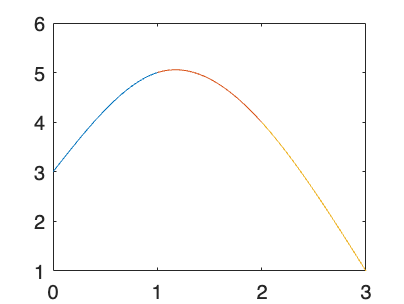

% Problem 3
clear
%a
x = [0,1,2,3];
y = [3,5,4,1];
coef = splinecoeff(x,y);
% S1
x1 = 0:0.01:1;
y1 = y(1) + coef(1,1)*(x1 - x(1)) + coef(1,2)*(x1 - x(1)).^2 ...
    + coef(1,3)*(x1 - x(1)).^3;
%S2
x2 = 1:0.01:2;
y2 = y(2) + coef(2,1)*(x2 - x(2)) + coef(2,2)*(x2 - x(2)).^2 ...
    + coef(2,3)*(x2 - x(2)).^3;
% S3
x3 = 2:0.01:3;
y3 = y(3) + coef(3,1)*(x3 - x(3)) + coef(3,2)*(x3 - x(3)).^2 ...
    + coef(3,3)*(x3 - x(3)).^3;

% Plot 3 splines
plot(x1,y1)
hold on 
plot(x2,y2)
plot(x3,y3)

% Problem 3
%b
x = [1960, 1970, 1990, 2000];
y = [3039585530,3707475887,5281653820,6079603571];
coef = splinecoeff(x,y);
x0 = 1980;
y1980 = y(2) + coef(2,1)*(x0 - x(2)) + coef(2,2)*(x0 - x(2)).^2 ...
    + coef(2,3)*(x0 - x(2)).^3;
erro = (y1980 - 4452584592)/4452584592

erro = 0.0040

% the error is around 0.4% which is very low

% Problem 4
clear
% choose c to be the mid point of [a,b]
syms x
%a
int_fa = integral(@(x) x.^2, 0, 1)

int_fa = 0.3333

%fa = x^2
fa(x) = x^2

$$fa(x) = x^{2}$$

% m= 1
error = round(comptrap(fa,0,1,1) - int_fa,5)

$$error = 0$$

% m= 2
error = round(comptrap(fa,0,1,2) - int_fa,5)

$$error = 0$$

% m= 4
error = round(comptrap(fa,0,1,4) - int_fa,5)

$$error = 0$$


%b
int_fb = integral(@(x) cos(x), 0, pi/2)

int_fb = 1.0000

%fb = cos(x)
fb(x) = cos(x)

$$fb(x) = \cos\left(x\right)$$

% m= 1
error = round(comptrap(fb,0,pi/2,1) - int_fb, 5)

$$error = 0.01378$$

% m= 2
error = round(comptrap(fb,0,pi/2,2) - int_fb, 5)

$$error = 0.00516$$

% m= 4
error = round(comptrap(fb,0,pi/2,4) - int_fb, 5)

$$error = 0.00139$$


%b
int_fc = integral(@(x) exp(x), 0, 1)

int_fc = 1.7183

%fc = e^x
fc(x) = exp(x)

$$fc(x) = {\mathrm{e}}^{x}$$

% m= 1
error = round(comptrap(fc,0,1,1) - int_fc, 5)

$$error = 0.00347$$

% m= 2
error = round(comptrap(fc,0,1,2) - int_fc, 5)

$$error = 0.0013$$

% m= 4
error = round(comptrap(fc,0,1,4) - int_fc, 5)

$$error = 0.00035$$

% Problem 5
clear
syms x
%a
f(x) = x^3;
round(simpson(f, 0, 1, 32), 5)

$$ans = 1.36461$$

%b
f(x) = tan(x);
round(simpson(f, 0, pi/4, 32), 5)

$$ans = 1.16924$$

%c
f(x) = atan(x);
round(simpson(f, 0, 1, 32), 5)

$$ans = 1.32106$$

function c=newtdd(x,y,n)% Newton's Divided Diferences
    v = zeros(n);
    c = zeros(n,1);

    for j=1:n
        v(j,1)=y(j);
    end

    for i=2:n
        for j=1:n+1-i
            v(j,i)=(v(j+1,i-1)-v(j,i-1))/(x(j+i-1)-x(j));
        end
    end

    for i=1:n
    c(i)=v(1,i);
    end
end

%Program 0.1 Nested multiplication
%Evaluates polynomial from nested form using Horner's method
%Input: degree d of polynomial,
%       array of d+1 coefficients (constant term first),
%       x-coordinate x at which to evaluate, and
%       array of d base points b, if needed
%Output: value y of polynomial at x
function y=nest(d,c,x,b)
    if nargin<4, b=zeros(d,1); 
    end 
y=c(d+1);
for i=d:-1:1
  y = y.*(x-b(i))+c(i);
end
end

function y=exp_chev( n)
b=cos((1:2:2*n-1)*pi/(2*n));
yb=exp(-b.^2); 
c=newtdd(b,yb,n);
x = -1:0.01:1;
y = nest(n-1,c,x,b);
end

% spline coefficient
%Program 3.5 Calculation of spline coefficients
%Calculates coefficients of cubic spline
%Input: x,y vectors of data points
% plus two optional extra data v1, vn
%Output: matrix of coefficients b1,c1,d1;b2,c2,d2;...
function coeff=splinecoeff(x,y)
n=length(x);v1=0;vn=0;
A=zeros(n,n); % matrix A is nxn
r=zeros(n,1);
for i=1:n-1 % define the deltas
dx(i)= x(i+1)-x(i); dy(i)=y(i+1)-y(i);
end
for i=2:n-1 % load the A matrix
A(i,i-1:i+1)=[dx(i-1) 2*(dx(i-1)+dx(i)) dx(i)];
r(i)=3*(dy(i)/dx(i)-dy(i-1)/dx(i-1)); % right-hand side
end
% Set endpoint conditions
% Use only one of following 5 pairs:
A(1,1) = 1; % natural spline conditions
A(n,n) = 1;
%A(1,1)=2;r(1)=v1; % curvature-adj conditions
%A(n,n)=2;r(n)=vn;
%A(1,1:2)=[2*dx(1) dx(1)];r(1)=3*(dy(1)/dx(1)-v1); %clamped
%A(n,n-1:n)=[dx(n-1) 2*dx(n-1)];r(n)=3*(vn-dy(n-1)/dx(n-1));
%A(1,1:2)=[1 -1]; % parabol-term conditions, for n>=3
%A(n,n-1:n)=[1 -1];
%A(1,1:3)=[dx(2) -(dx(1)+dx(2)) dx(1)]; % not-a-knot, for n>=4
%A(n,n-2:n)=[dx(n-1) -(dx(n-2)+dx(n-1)) dx(n-2)];
coeff=zeros(n,3);
coeff(:,2)=A\r; % solve for c coefficients
for i=1:n-1 % solve for b and d
coeff(i,3)=(coeff(i+1,2)-coeff(i,2))/(3*dx(i));
coeff(i,1)=dy(i)/dx(i)-dx(i)*(2*coeff(i,2)+coeff(i+1,2))/3;
end
coeff=coeff(1:n-1,1:3);
end

%function for composite trapezoid rule with m panels
% choose mid point c = (b-a)/2
function y = comptrap(f,a,b,m)
c = (b-a)/2;
f2 = diff(f, 2);
xi = linspace(a,b,m+1);
yi = f(xi);
h = (b-a)/(m);
% f(a) + f(b) + 2*sigma(f, 1, m-1) = 2*sigma(f, 0, m) - f(a) - f(b)
y = (h/2)*(2*sum(yi(2:1:m)) + f(a) + f(b)) - (b-a)*h^2*f2(c)/12;
end

%function for composite simpson rule with m panels
function y = simpson(f, a, b, m)
% choose mid point c = (b-a)/2
c = (b-a)/2;
D = diff(f);
arc = sqrt(1 + D);
arc4 = diff(arc, 4);
h = (b-a)/(2*m);
xi = linspace(a,b,2*m+1);
yi = arc(xi);
y = (h/3)*(arc(a) + arc(b) + 4*sum(yi(3:2:2*m-1))...
    + 2*sum(yi(2:2:(2*m)))) - (b-a)*h^4*arc4(c)/180;
end
